clear
clc

opts = optimoptions('fmincon','SpecifyObjectiveGradient',true,'Display','iter','FunctionTolerance',1e-4,'MaxFunctionEvaluations',150);

tic
[xv,Rv] = fmincon(@(x) objective(x),[0.5 0.9 1.6 0.4 10 8],[],[],[],[],[0 0 0 0 0 0],[3 3 3 3 100 100],[],opts)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.817171e+02    0.000e+00    1.620e+02
    1       2    1.197357e+02    0.000e+00    4.549e+02    2.557e+00
    2       3    6.791450e-02    0.000e+00    7.321e+01    3.208e-01
    3      17    3.386126e-02    0.000e+00    5.424e+01    8.953e-04
    4      19    3.301684e-02    0.000e+00    5.418e+01    5.686e-04
    5      24    2.188054e-02    0.000e+00    8.784e-01    1.489e-03
    6      26    2.185560e-02    0.000e+00    8.781e-01    1.891e-05
    7      27    5.866148e-01    0.000e+00    4.213e+02    2.147e-01
    8      29    1.420017e-01    0.000e+00    1.650e+02    2.320e-01
    9      33    5.508767e-02    0.000e+00    4.865e+01    1.002e-01
   10      34    6.686348e-02    0.000e+00    3.764e+01    1.617e-01
   11      35    1.141208e-02    0.000e+00    2.279e+01    3.322e-02
   12      36    2.095439e-02    0.000e+00    5

xv =     2.2542    0.8192    2.2646    0.2600   17.3230    6.6539


Rv = 6.0295e-07

toc

Elapsed time is 135.263996 seconds.


xv

xv =     2.2542    0.8192    2.2646    0.2600   17.3230    6.6539



A = AutoDiff([xv(1) xv(2) xv(3) xv(4) xv(5) xv(6)]);

tic
[tf, yf] = ODE.rkf45(@(t,y) ODE.test.PredatorPreyRHS(t,y,A(1),A(2),A(3),A(4)), [A(5);A(6)], 0, 10, 0.01,  1e-9, A);
toc

Elapsed time is 3.856855 seconds.



L = sum((yf{end} - [10;10]).^2);

dL = full(getderivs(L))

dL = 1.0e+03 *

    0.2200   -0.7052    0.1791   -1.2425   -0.0299   -0.1058


L = getvalue(L)

L = 64.0808

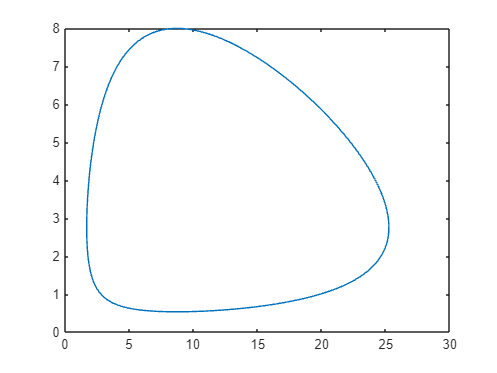


yfv=[];
dyfv=[];

for i = 1:length(tf)
    yfv(:,i) = getvalue(yf{i});
    dyfv(:,:,i) = full(getderivs(yf{i}));
end

figure
plot(yfv(1,:),yfv(2,:))

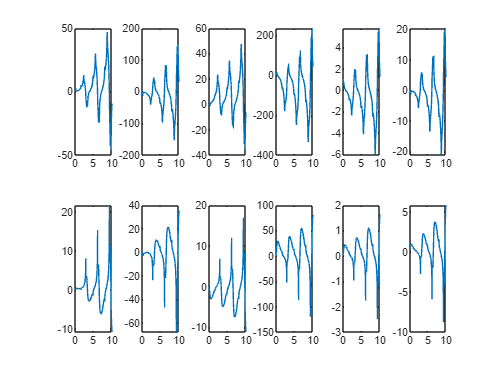


[nx,ny,~] = size(dyfv);

figure
k=0;
for i = 1:nx
    for j = 1:ny
        k=k+1;
        subplot(nx,ny,k)
        plot(tf,squeeze(dyfv(i,j,:)))
    end
end

function [L,dL] = objective(x)

A = AutoDiff([x(1) x(2) x(3) x(4) x(5) x(6)]);

[~, yf] = ODE.feuler(@(t,y) ODE.test.PredatorPreyRHS(t,y,A(1),A(2),A(3), A(4)), [A(5);A(6)], 0, 10, 0.01, A);

L = sum((yf{end} - [10;10]).^2);

dL = full(getderivs(L));
L = getvalue(L);

end